%ORGINALNE ZDJECIE
zdjecie=imread("obrazeczek.jpg");
%zdjecie = rgb2gray(zdjecie);
[szerokosc, dlugosc]= size(zdjecie);
"przed zmiana"

ans = "przed zmiana"

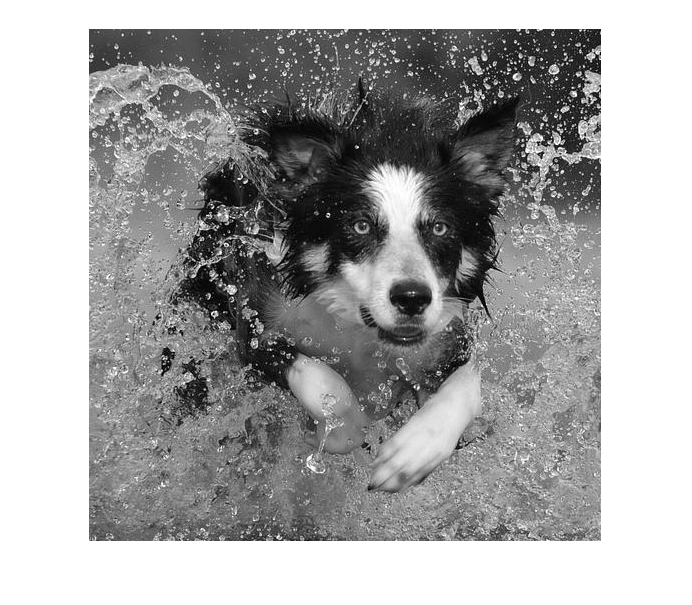

imshow(zdjecie);

szyfr=fopen("tex.txt");
szyfr=fread(szyfr,'ubit1');
zdjecie=reshape(zdjecie,[],1);
zdjecie=de2bi(zdjecie);


%zmiana obrazu
for i=1:length(szyfr)
    zdjecie(i,1)=szyfr(i);
end
"po zmianie"

ans = "po zmianie"

szyfr;

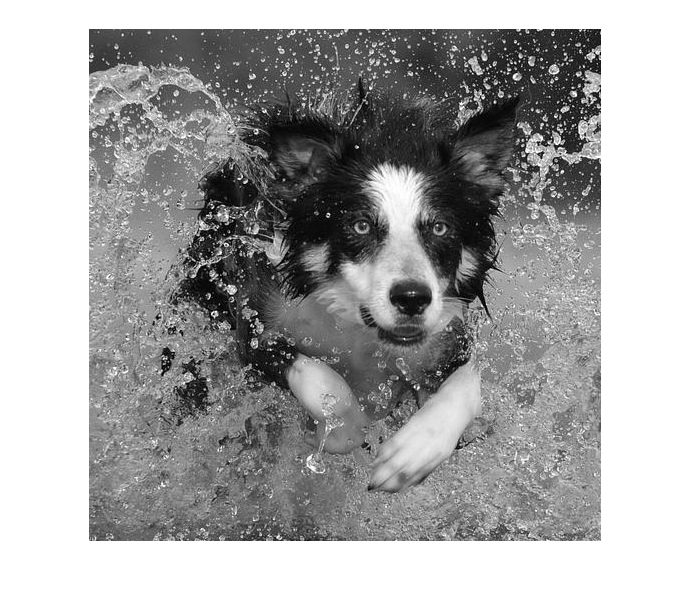

%zgranie obrazu
zdjecie=bi2de(zdjecie);
zdjecie=reshape(zdjecie,szerokosc,dlugosc);
imshow(zdjecie);

imwrite(zdjecie,"zakodowany.png");

%odczytanie kodu calego
zdjecie=imread("zakodowany.png");
t=fopen("odkodowany.txt","W");
[szerokosc, dlugosc]= size(zdjecie);
zdjecie=reshape(zdjecie,[],1);
zdjecie=de2bi(zdjecie);
for i=1:length(zdjecie)
    kod(i)=zdjecie(i,1);
end
kodzik=reshape(kod,8,[]);
kodzik=kodzik';
kodzik=bi2de(kodzik);
fwrite(t,kodzik);
kodzik=char(kodzik)

kodzik = 32768×1 char array
    'f'
    'r'
    'y'
    't'
    'k'
    'i'
    ' '
    'z'
    ' '
    'k'
    'e'
    'c'
    'z'
    'u'
    'p'
    'e'
    'm'
    'ê'
    'L'
    ''
    '×'
    ''
    'x'
    'Ò'
    'Ù'
    '('
    'ð'
    'Ó'
    '¦'
    'ë'
    '©'
    ''
    's'
    'Ú'
    'à'
    'ð'
    'w'
    'u'
    'º'
    'Q'
    'a'
    '&'
    ''
    '¤'
    'Í'
    'z'
    'Ì'
    'W'
    '¬'
    'ó'
    ''
    '¯'
    '7'
    '+'
    ''
    'n'
    'e'
    '
    ''
    'º'
    ''
    'K'
    'C'
    ''
    'x'
    ''
    'F'
    ''
    '='
    'ª'
    'Ú'
    'F'
    'L'
    'ó'
    ''
    ''
    '¢'
    ''
    ''
    ''
    'X'
    'a'
    'Í'
    '¥'
    'Á'
    '>'
    'A'
    '©'
    'v'
    'U'
    ''
    ' '
    ':'
    '²'
    'A'
    '·'
    'ò'
    'Q'
    '×'
    'q'
    't'
    ' '
    ''
    '³'
    '2'
    'B'
    ''
    'ù'
    ''
    ''
    '^'
    'Ú'
    'Î'
    'ª'
    '('
    'Ö'
    'N'
    'L'
    'ç'
    '/'
    'q'
    ''
    ''
    'Q'
    '

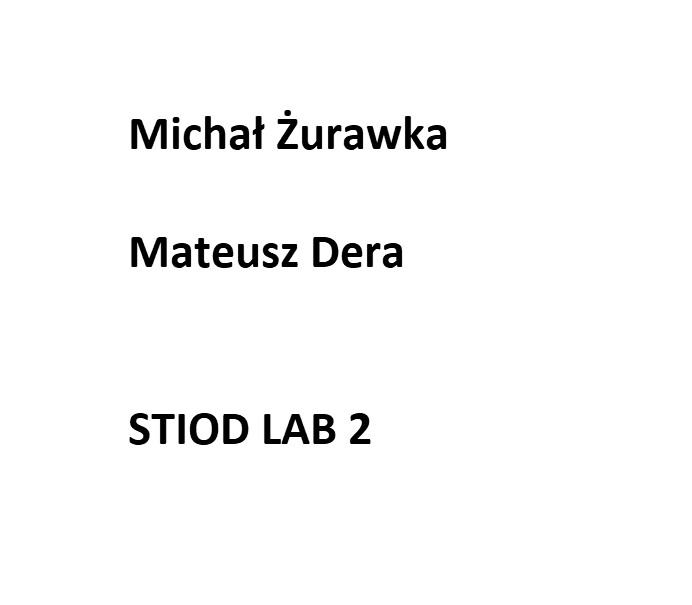

%wgranie obrazu oraz przystosowanie
nowe=imread("obraz.jpg");
nowe = rgb2gray(nowe);
imshow(uint8(nowe))
colormap('gray');

[szerokosc1, dlugosc1]= size(nowe);

for i=1: szerokosc1
    for j=1: dlugosc1
        if nowe(i,j)<127
            nowe(i,j)=0;
        else
            nowe(i,j)=1;
        end
    end
end
nowe=reshape(nowe,[],1);
nowe=de2bi(nowe);


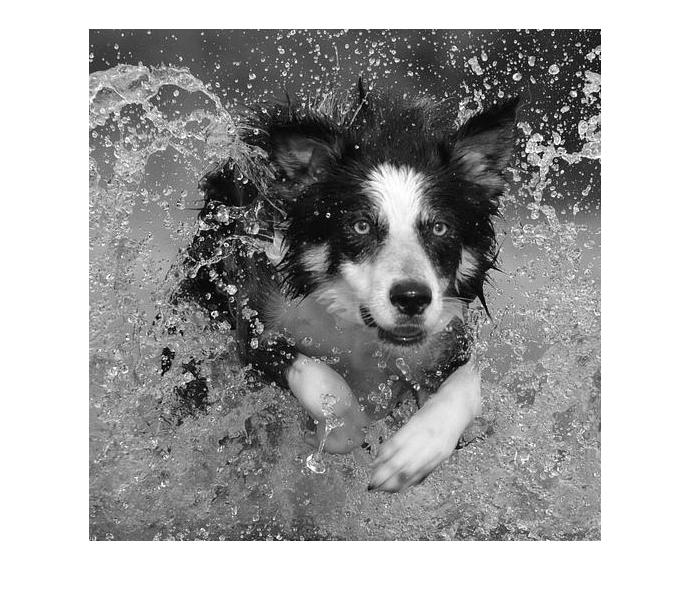

%zmiana obrazu
zdjecie=imread("obrazeczek.jpg");
zdjecie=reshape(zdjecie,[],1);
zdjecie=de2bi(zdjecie);


for i=1:length(zdjecie)
    zdjecie(i,1)=nowe(i);
end

zdjecie=bi2de(zdjecie);
zdjecie=reshape(zdjecie,szerokosc1,dlugosc1);
imshow(zdjecie);

imwrite(zdjecie,"scalone.png");


%odkodowanie
zdjecie=imread("scalone1.jpg");
zdjecie=reshape(zdjecie,[],1);
zdjecie=de2bi(zdjecie);

for i=1:length(zdjecie)
    kod(i)=zdjecie(i,1);
end
kodzik=reshape(kod,[],8);
odk=reshape(kodzik,512,512);

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.


for i=1: 512
    for j=1: 512
        if odk(i,j)==0
            odk(i,j)=0;
        else
            odk(i,j)=255;
        end
    end
end

imwrite(uint8(odk), 'napis.png');